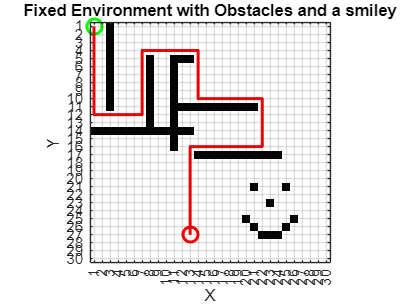

% A* with a fixed env

% Function to add rectangular obstacles to the environment
function environment = addRectangle(environment, topLeft, width, height)
    % topLeft: [x, y] coordinates of the top-left corner
    % width: horizontal size of the rectangle
    % height: vertical size of the rectangle
    
    % Define rectangle coordinates
    xStart = topLeft(1);
    yStart = topLeft(2);
    xEnd = min(xStart + width - 1, size(environment, 1)); % Ensure within bounds
    yEnd = min(yStart + height - 1, size(environment, 2)); % Ensure within bounds
    
    % Set obstacle cells to 1
    environment(xStart:xEnd, yStart:yEnd) = 1;
end

%------------------------------------------------------------------------%
% initialize environment
gridSize = [30, 30];
environment = zeros(gridSize);

% obstacles
environment = addRectangle(environment, [3, 1], 1, 11);   % 1x11 rectangle at (3,1)
environment = addRectangle(environment, [1, 14], 13, 1);  % 13x1 rectangle at (1,14)
environment = addRectangle(environment, [8, 5], 1, 10);    % 1x10 rectangle at (8,5)
environment = addRectangle(environment, [11, 5], 1, 12);  % 1x12 rectangle at (11,5)
environment = addRectangle(environment, [12, 5], 2, 1);   % 2x1 rectangle at (12,5)
environment = addRectangle(environment, [12, 11], 10, 1); % 10x1 rectangle at (12,11)
environment = addRectangle(environment, [14, 17], 11, 1); % 11x1 rectangle at (14,17)

% the smiley face
environment = addRectangle(environment, [21, 21], 1, 1); % left eye
environment = addRectangle(environment, [25, 21], 1, 1); % right eye
environment = addRectangle(environment, [23, 23], 1, 1); % nose

environment = addRectangle(environment, [20, 25], 1, 1); % smile1
environment = addRectangle(environment, [21, 26], 1, 1); % smile2
environment = addRectangle(environment, [22, 27], 1, 1); % smile3
environment = addRectangle(environment, [23, 27], 1, 1); % smile4
environment = addRectangle(environment, [24, 27], 1, 1); % smile5
environment = addRectangle(environment, [25, 26], 1, 1); % smile6
environment = addRectangle(environment, [26, 25], 1, 1); % smile7

% Defining start and goal points
startNode = [1, 1]; %[x,y]
goalNode = [13, 27]; %[x,y]

%------------------------------------------------------------------------%

% Visualize the environment
figure;
set(gcf, 'Color', [1 1 1]); 
imagesc(~environment'); 
colormap(gray);
hold on;
plot(startNode(1), startNode(2), 'go', 'MarkerSize', 10, 'LineWidth', 2); % Start
plot(goalNode(1), goalNode(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);   % Goal
title('Fixed Environment with Obstacles and a smiley');
xlabel('X'); ylabel('Y');
grid on;

axis equal tight;  % Equal scaling
set(gca, 'XTick', 1:gridSize(1), 'YTick', 1:gridSize(2)); % Setting ticks to match grid cells
set(gca, 'XLim', [0.5, gridSize(1) + 0.5], 'YLim', [0.5, gridSize(2) + 0.5]); % Fitting grid boundaries

%  A* Implementation 

[path, ~] = runAStar(environment, startNode, goalNode);

% Plot the resulting path
if ~isempty(path)
    % Adjusting path coordinates for transposed visualization
    adjustedPath = path(:, [1, 2]); 
    plot(adjustedPath(:, 1), adjustedPath(:, 2), 'r', 'LineWidth', 2); % Corrected path visualization
else
    disp('No path found!');
end


%------------------------------------------------------------------------%
% A*
function [path, closedSet] = runAStar(environment, startNode, goalNode)
    % Grid size
    gridSize = size(environment);
    grid = environment;

    % Heuristic function (Manhattan distance)
    heuristic = @(node, goal) abs(node(1) - goal(1)) + abs(node(2) - goal(2));

    % Initialize open and closed sets with parent field
    openSet = [];
    openSet(1).pos = startNode;
    openSet(1).g = 0;
    openSet(1).f = heuristic(startNode, goalNode);
    openSet(1).parent = [];

    closedSet = [];

    % Main A* loop
    while ~isempty(openSet)
        % Find node with the lowest f-score
        [~, idx] = min([openSet.f]);
        current = openSet(idx);

        % Check if goal is reached
        if isequal(current.pos, goalNode)
            path = reconstructPath(current, closedSet);
            return;
        end

        % Move current node to closed set
        closedSet = [closedSet; current];
        openSet(idx) = [];

        % Get neighbors (up, down, left, right)
        neighbor_offsets = [0 1; 1 0; 0 -1; -1 0];
        neighbors = neighbor_offsets + current.pos;

        for i = 1:size(neighbors, 1)
            neighbor = neighbors(i, :);

            % Skip if out of bounds or obstacle
            if neighbor(1) < 1 || neighbor(2) < 1 || ...
               neighbor(1) > gridSize(1) || neighbor(2) > gridSize(2) || ...
               grid(neighbor(1), neighbor(2)) == 1
                continue;
            end

            % Calculate g and f scores
            tentative_g = current.g + 1;
            f = tentative_g + heuristic(neighbor, goalNode);

            % Check if neighbor is in open set
            existing = arrayfun(@(x) isequal(x.pos, neighbor), openSet);
            if ~any(existing)
                % Add neighbor to open set
                openSet(end+1).pos = neighbor; 
                openSet(end).g = tentative_g;
                openSet(end).f = f;
                openSet(end).parent = current.pos;
            else
                idx_neighbor = find(existing);
                if tentative_g < openSet(idx_neighbor).g
                    % Update neighbor with better path
                    openSet(idx_neighbor).g = tentative_g;
                    openSet(idx_neighbor).f = f;
                    openSet(idx_neighbor).parent = current.pos;
                end
            end
        end
    end

    % No path found
    path = [];
end

function path = reconstructPath(current, closedSet)
    path = current.pos; % Start with the goal node's position
    while ~isempty(current.parent)
        parentPos = current.parent;
        
        % Find the parent node in closedSet
        idx = find(arrayfun(@(x) isequal(x.pos, parentPos), closedSet), 1);
        if isempty(idx)
            error('Parent node not found in closed set. Path reconstruction failed.');
        end
        
        current = closedSet(idx); % Move to parent node
        path = [current.pos; path]; 
    end
end
